# Transformation: Hints & Cues

Follow this order to stablish the ordered transformations

## Part of reference

clear
close all
clf
v= [0 0 0;1 0 0;1 1 0;0 1 0;0 0 1;1 0 1;1 1 1;0 1 1]

v =      0     0     0
     1     0     0
     1     1     0
     0     1     0
     0     0     1
     1     0     1
     1     1     1
     0     1     1


f = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8]

f =      1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8
     1     2     3     4
     5     6     7     8


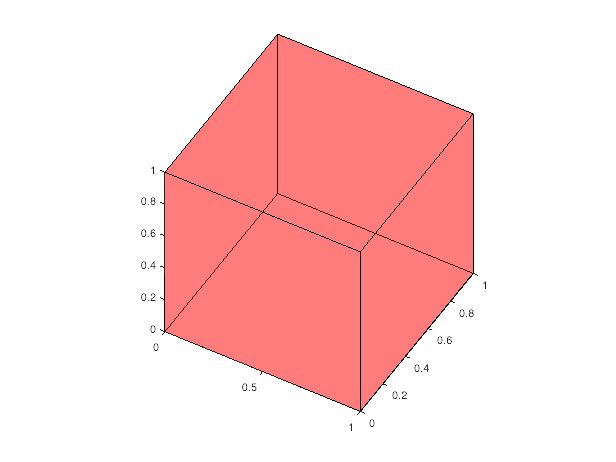

patch('Vertices',v,'Faces',f,'FaceVertexCData',hsv(6),'FaceColor','r','FaceAlpha',0.3)
view(30,45)
axis equal

## Part 1

At origen

### Scaling vertices and visualize it

H=2

H = 2

W=0.9

W = 0.9000

D=0.08

D = 0.0800

v_1=[H 0 0;0 W 0;0 0 D]*v'

v_1 =          0    2.0000    2.0000         0         0    2.0000    2.0000         0
         0         0    0.9000    0.9000         0         0    0.9000    0.9000
         0         0         0         0    0.0800    0.0800    0.0800    0.0800


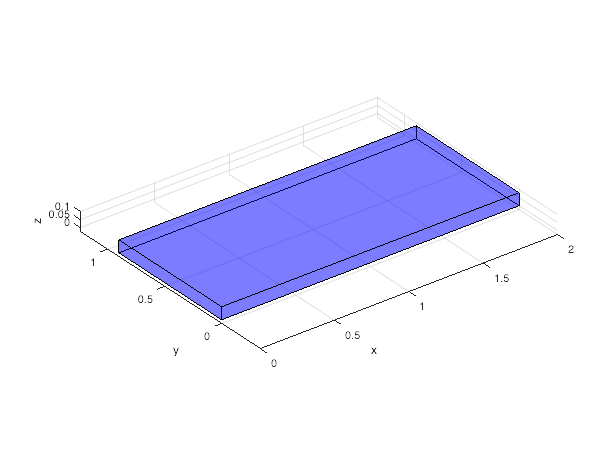

figure
patch('Vertices',v_1(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','b','FaceAlpha',0.3)
grid on
xyzlabel
axis equal
view(3)

## Part 2

At origen

### Scaling vertices and visualize it

H=1.6 % x

H = 1.6000

W=0.6 % y

W = 0.6000

D=0.2 % z

D = 0.2000

v_2=[H 0 0;0 W 0;0 0 D]*v'

v_2 =          0    1.6000    1.6000         0         0    1.6000    1.6000         0
         0         0    0.6000    0.6000         0         0    0.6000    0.6000
         0         0         0         0    0.2000    0.2000    0.2000    0.2000


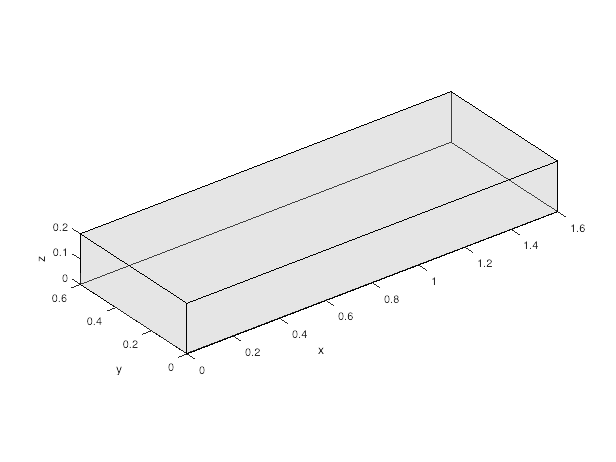

figure
patch('Vertices',v_2','Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.8 0.8 0.8],'FaceAlpha',0.3)
view(3)
xyzlabel
axis equal

## Part 3

At origen

### Scaling vertices and visualize it

H=0.15 % x

H = 0.1500

W=0.20 % y

W = 0.2000

D=0.17 % z

D = 0.1700

v_3=[H 0 0;0 W 0;0 0 D]*v'

v_3 =          0    0.1500    0.1500         0         0    0.1500    0.1500         0
         0         0    0.2000    0.2000         0         0    0.2000    0.2000
         0         0         0         0    0.1700    0.1700    0.1700    0.1700


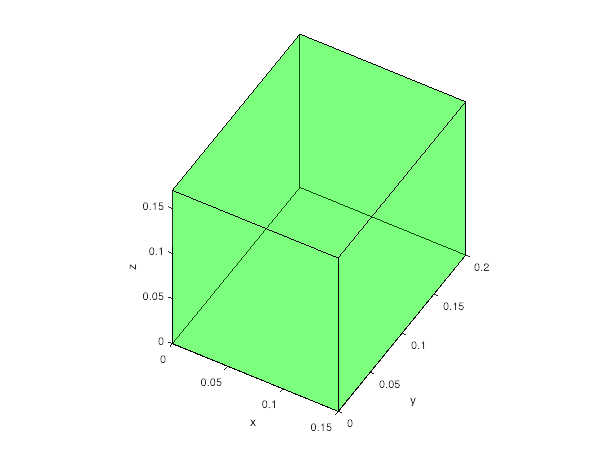

figure
patch('Vertices',v_3','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','g','FaceAlpha',0.3)
view(30,45)
xyzlabel
axis equal

## Point 

With respect to Referece Frame {I}

[X,Y,Z] = sphere;

Plot a 16mm sphere centered at the origin.

r=0.016 % 16 mm

r = 0.0160

xyz_p=[H/2 W/3 D/4 1]'

xyz_p =     0.0750
    0.0667
    0.0425
    1.0000


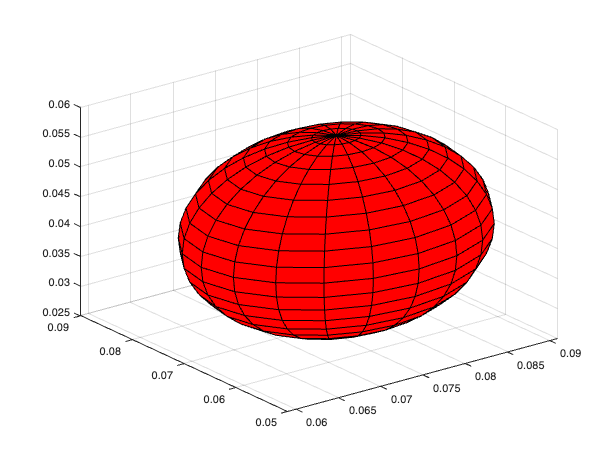

figure
surf(X*r+xyz_p(1),Y*r+xyz_p(2),Z*r+xyz_p(3),'FaceColor',[1 0 0])

## Transformations. 

### T_1_0. Desired pose

T_1_0=transl(-0.3,-0.5,0)*trotz(pi/3)

T_1_0 =     0.5000   -0.8660         0   -0.3000
    0.8660    0.5000         0   -0.5000
         0         0    1.0000         0
         0         0         0    1.0000


### T_2_1

T_2_1=transl(0.4,0.15,0.1)

T_2_1 =     1.0000         0         0    0.4000
         0    1.0000         0    0.1500
         0         0    1.0000    0.1000
         0         0         0    1.0000


T_2_0=T_1_0*T_2_1

T_2_0 =     0.5000   -0.8660         0   -0.2299
    0.8660    0.5000         0   -0.0786
         0         0    1.0000    0.1000
         0         0         0    1.0000


### T_3_2

Auxiliar Reference Frame, i.e transformation

T_3_2=transl(1.75,0.2,0)

T_3_2 =     1.0000         0         0    1.7500
         0    1.0000         0    0.2000
         0         0    1.0000         0
         0         0         0    1.0000


T_3_0=T_2_0*T_3_2

T_3_0 =     0.5000   -0.8660         0    0.4719
    0.8660    0.5000         0    1.5370
         0         0    1.0000    0.1000
         0         0         0    1.0000


### T_I_3

T_I_3=trotz(-pi/2)*trotx(-pi/2)*transl(-W, -H,0)

T_I_3 =          0         0    1.0000         0
   -1.0000         0         0    0.2000
         0   -1.0000         0    0.1500
         0         0         0    1.0000


T_I_0=T_3_0*T_I_3

T_I_0 =     0.8660         0    0.5000    0.2987
   -0.5000         0    0.8660    1.6370
         0   -1.0000         0    0.2500
         0         0         0    1.0000


## Operating vertices

v_1(4,:)=1

v_1 =          0    2.0000    2.0000         0         0    2.0000    2.0000         0
         0         0    0.9000    0.9000         0         0    0.9000    0.9000
         0         0         0         0    0.0800    0.0800    0.0800    0.0800
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


v_1_0=T_1_0*v_1

v_1_0 =    -0.3000    0.7000   -0.0794   -1.0794   -0.3000    0.7000   -0.0794   -1.0794
   -0.5000    1.2321    1.6821   -0.0500   -0.5000    1.2321    1.6821   -0.0500
         0         0         0         0    0.0800    0.0800    0.0800    0.0800
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


v_2(4,:)=1

v_2 =          0    1.6000    1.6000         0         0    1.6000    1.6000         0
         0         0    0.6000    0.6000         0         0    0.6000    0.6000
         0         0         0         0    0.2000    0.2000    0.2000    0.2000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


v_2_p=T_2_0*v_2

v_2_p =    -0.2299    0.5701    0.0505   -0.7495   -0.2299    0.5701    0.0505   -0.7495
   -0.0786    1.3071    1.6071    0.2214   -0.0786    1.3071    1.6071    0.2214
    0.1000    0.1000    0.1000    0.1000    0.3000    0.3000    0.3000    0.3000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


v_3(4,:)=1

v_3 =          0    0.1500    0.1500         0         0    0.1500    0.1500         0
         0         0    0.2000    0.2000         0         0    0.2000    0.2000
         0         0         0         0    0.1700    0.1700    0.1700    0.1700
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


v_3_p=T_3_0*v_3

v_3_p =     0.4719    0.5469    0.3737    0.2987    0.4719    0.5469    0.3737    0.2987
    1.5370    1.6669    1.7669    1.6370    1.5370    1.6669    1.7669    1.6370
    0.1000    0.1000    0.1000    0.1000    0.2700    0.2700    0.2700    0.2700
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Point_U=T_I_0*xyz_p

Point_U =     0.3849
    1.6363
    0.1833
    1.0000


## Plotting parts

figure
hold on
patch('Vertices',v_1_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','b','FaceAlpha',0.3)
patch('Vertices',v_2_p(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.8 0.8 0.8],'FaceAlpha',0.3)
patch('Vertices',v_3_p(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','g','FaceAlpha',0.3)
view(30,45)
grid on
xyzlabel
axis equal
axis([-1.5 1.5 -1.5 3.5 -0.5 2.5])

Plotting point wrt {U}

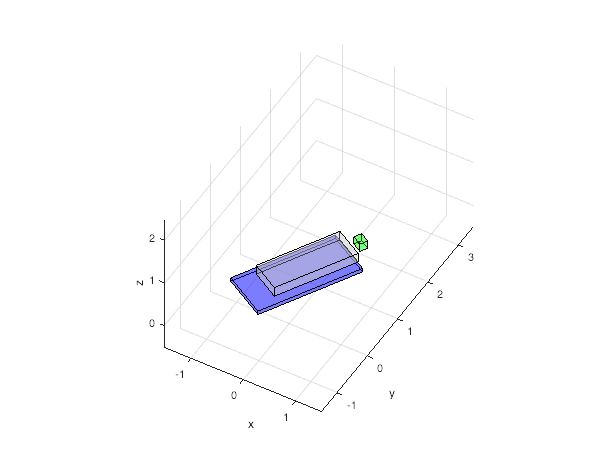

surf(X*r+Point_U(1),Y*r+Point_U(2),Z*r+Point_U(3),'FaceColor',[1 0 0])

## Reference frames

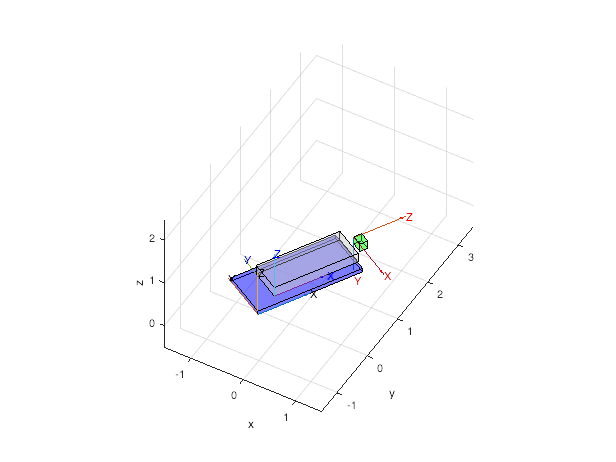

trplot(T_1_0,'framelabel','T' ,'color', 'black','arrow','width',0.4)
trplot(T_2_0,'framelabel','B' ,'color', 'b','arrow','width',0.4)
trplot(T_I_0,'framelabel','I' ,'color', 'r','arrow','width',0.4)